# Logistic Regression for Titanic data classification 

## Load the Titanic data and show it

clc
clear
Train= readtable('train.csv');
Test = readtable('test.csv');
head(Train)

ans = 8×12 table
    PassengerId    Survived    Pclass                            Name                               Sex       Age    SibSp    Parch          Ticket           Fare     Cabin     Embarked
    ___________    ________    ______    _____________________________________________________    ________    ___    _____    _____    __________________    ______    ______    ________

    1              0           3         'Braund, Mr. Owen Harris'                                'male'       22    1        0        'A/5 21171'             7.25    ''        'S'     
    2              1           1         'Cumings, Mrs. John Bradley (Florence Briggs Thayer)'    'female'     38    1        0        'PC 17599'            71.283    'C85'     'C'     
    3              1           3         'Heikkinen, Miss. Laina'                                 'female'     26    0        0        'STON/O2. 3101282'     7.925    ''        'S'     
    4              1           1         'Futrelle, 

head(Test)

ans = 8×11 table
    PassengerId    Pclass                         Name                           Sex       Age     SibSp    Parch     Ticket       Fare     Cabin    Embarked
    ___________    ______    ______________________________________________    ________    ____    _____    _____    _________    ______    _____    ________

    892            3         'Kelly, Mr. James'                                'male'      34.5    0        0        '330911'     7.8292    ''       'Q'     
    893            3         'Wilkes, Mrs. James (Ellen Needs)'                'female'      47    1        0        '363272'          7    ''       'S'     
    894            2         'Myles, Mr. Thomas Francis'                       'male'        62    0        0        '240276'     9.6875    ''       'Q'     
    895            3         'Wirz, Mr. Albert'                                'male'        27    0        0        '315154'     8.6625    ''       'S'     
    896            3         'Hirv

## Make the prediction by "sex"


disp(grpstats(Train(:,{'Survived','Sex'}), 'Sex'))

                Sex       GroupCount    mean_Survived
              ________    __________    _____________

    male      'male'      577           0.18891      
    female    'female'    314           0.74204      



gendermdl = grpstats(Train(:,{'Survived','Sex'}), {'Survived','Sex'});
all_female = (gendermdl.GroupCount('0_male') + gendermdl.GroupCount('1_female'))/(577+314);
disp(all_female)

    0.7868



## Preprocess the NaN values

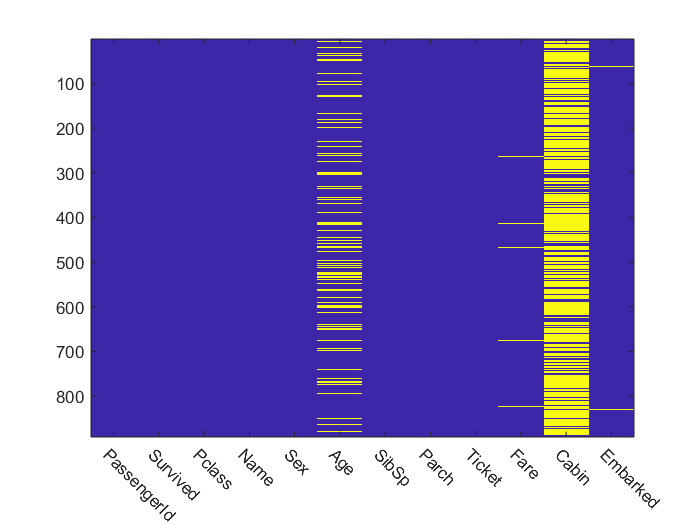

Train.Fare(Train.Fare == 0) = NaN;      % treat 0 fare as NaN
Train.Fare(Train.Fare == 0) = NaN;        % treat 0 fare as NaN
vars = Train.Properties.VariableNames;  % extract column names
figure
imagesc(ismissing(Train))
set(gca,'XTick', 1:12,'XTickLabel',vars);
xtickangle(-45)

% Using the average age replace NaN age
avgAge = nanmean(Train.Age)             % get average age

avgAge = 29.6991

Train.Age(isnan(Train.Age)) = avgAge;   % replace NaN with the average
Test.Age(isnan(Test.Age)) = avgAge; 


% Replace the NaN Fare with the average fare of the correspoinding Pclass
fare = grpstats(Train(:,{'Pclass','Fare'}),'Pclass');   % get class average
disp(fare)

         Pclass    GroupCount    mean_Fare
         ______    __________    _________

    1    1         216           86.149   
    2    2         184           21.359   
    3    3         491           13.788   



for i = 1:height(fare) % for each |Pclass|
    % apply the Pclass average to missing values
    Train.Fare(Train.Pclass == i & isnan(Train.Fare)) = fare.mean_Fare(i);
    Test.Fare(Test.Pclass == i & isnan(Test.Fare)) = fare.mean_Fare(i);
end

% Multi Cabins，No Cabin etc.

train_cabins = cellfun(@strsplit, Train.Cabin, 'UniformOutput', false);
test_cabins = cellfun(@strsplit, Test.Cabin, 'UniformOutput', false);
 
% count the number of tokens
Train.nCabins = cellfun(@length, train_cabins);
Test.nCabins = cellfun(@length, test_cabins);
 
% deal with exceptions - only the first class people had multiple cabins
Train.nCabins(Train.Pclass ~= 1 & Train.nCabins > 1,:) = 1;
Test.nCabins(Test.Pclass ~= 1 & Test.nCabins > 1,:) = 1;
 
% if |Cabin| is empty, then |nCabins| should be 0
Train.nCabins(cellfun(@isempty, Train.Cabin)) = 0;
Test.nCabins(cellfun(@isempty, Test.Cabin)) = 0;

% Embarked is not available
% get most frequent value
disp(grpstats(Train(:,{'Survived','Embarked'}), 'Embarked'))

         Embarked    GroupCount    mean_Survived
         ________    __________    _____________

    S    'S'         644           0.33696      
    C    'C'         168           0.55357      
    Q    'Q'          77           0.38961      



 
% apply it to missling value
for i = 1 : 891
    if isempty(Train.Embarked{i})
        Train.Embarked{i}='S';
    end
end
 
for i = 1 : 418
    if isempty(Test.Embarked{i})
        Test.Embarked{i}='S';
    end
end
 
% convert the data type from categorical to double
Train.Embarked = double(cell2mat(Train.Embarked));
Test.Embarked = double(cell2mat(Test.Embarked));

% change Sex to tpye "double"
for i = 1 : 891
    if strcmp(Train.Sex{i} ,'male')
        Train.Sex{i}=1;
    else
        Train.Sex{i}=0;
    end
end
 
for i = 1 : 418
    if strcmp(Test.Sex{i} ,'male')
        Test.Sex{i}=1;
    else
        Test.Sex{i}=0;
    end
end
Train.Sex = cell2mat(Train.Sex);
Test.Sex = cell2mat(Test.Sex);

% Del some columns
Train(:,{'Name','Ticket','Cabin'}) = [];
Test(:,{'Name','Ticket','Cabin'}) = [];


## Visulization

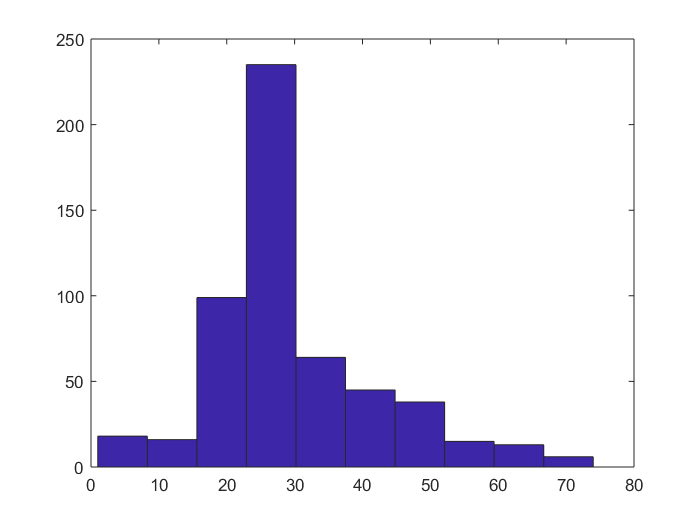


% Age - survived
figure
hist (Train.Age(Train.Survived == 0))   % age histogram of non-survivers

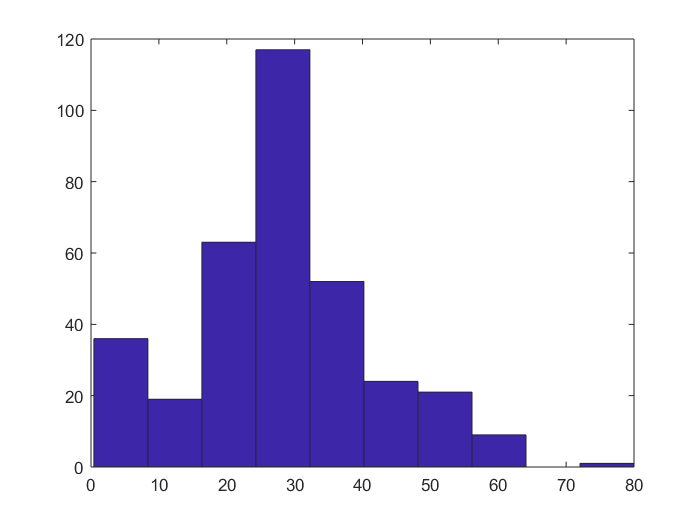

figure
hist (Train.Age(Train.Survived == 1))   % age histogram of survi

data = Train.Variables;
sur=0;
%计算700个测试集中存活的人数
for m=1:700
    if(data(m,2)==1)
        sur=sur+1;
    end
end
%对乘客年龄，票价进行分类（除十四舍五入）
data(:,5)=data(:,5)./10;
data(:,5)=round(data(:,5));
data(:,8)=data(:,8)./10;
data(:,8)=round(data(:,8));
sur1=sur/700;%p(w)
%从891个数据中挑选700个作为训练集
for i=701:891
    TT(i-700,:)=data(i,:);
end
%gailv函数返回矩阵，第一列为data第3(4,5...)列数据的所有分类，第二列为p(x),第三列p(x|w)
%en函数返回data第3(4,5...)的类别及p(w|x)
%a1,a2,a3...为每个特征的类别数量
x3=gailv(data,3,sur);
quan3=en(data,x3,3,sur1);
x4=gailv(data,4,sur);
quan4=en(data,x4,4,sur1);
a4=length(quan4(:,1));
x5=gailv(data,5,sur);
quan5=en(data,x5,5,sur1);
a5=length(quan5(:,1));
x6=gailv(data,6,sur);
quan6=en(data,x6,6,sur1);
a6=length(quan6(:,1));
x7=gailv(data,7,sur);
quan7=en(data,x7,7,sur1);
a7=length(quan7(:,1));
x8=gailv(data,8,sur);
quan8=en(data,x8,8,sur1);
a8=length(quan8(:,1));
x9=gailv(data,9,sur);
quan9=en(data,x9,9,sur1);
a9=length(quan9(:,1));
x10=gailv(data,10,sur);
quan10=en(data,x10,10,sur1);
a10=length(quan10(:,1));
%quan 1,2,3,4,5,6,7,8为特征情况下的概率
%将table数据转化为double类型
T=table2array(Test);
%对年龄及票价分类处理
T(:,4)=T(:,4)./10;
T(:,4)=round(T(:,4));
T(:,7)=T(:,7)./10;
T(:,7)=round(T(:,7));
%建立r1矩阵，abc函数功能为将TT（700个训练集）的每个特征对应的存活概率存至r1中
r1=zeros(191,8);
r1(:,1)=abc(TT,quan3,3,191);
r1(:,2)=abc(TT,quan4,4,191);
r1(:,3)=abc(TT,quan5,5,191);
r1(:,4)=abc(TT,quan6,6,191);
r1(:,5)=abc(TT,quan7,7,191);
r1(:,6)=abc(TT,quan8,8,191);
r1(:,7)=abc(TT,quan9,9,191);
r1(:,8)=abc(TT,quan10,10,191);
rat1=zeros(191,50)

rat1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

rat=zeros(191,100)

rat =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

%通过以下循环计算出采用那两组特征所预测正确结果数量最大，并将特征序号分别存至aa，bb
n=1;
count2=0;
righ=0;
for i=1:3
    rat(i,1)=i;
    if(i==2)
        for ji=1:7
            for m=ji+1:8
            rat(:,n)=r1(:,ji).*r1(:,m);
            for jj=1:191
                if(rat(jj,n)>0.5)
                    rat1(jj,n)=1;
                end
                if(rat1(jj,n)==data(TT(jj,1),2))
                        count2=count2+1;
                end
            end
            if(count2>righ)
            righ=count2;
            aa=ji;
            bb=m;
            end
            n=n+1;
            count2=0;
        end
    end
    right1=righ/191;
    end
end
%通过以上算法可以得出data中选用第三列，第四列(8个特征中第一列，第二列)得出的正确率最高
%通过以下循环计算测试集的存活率，存活率存至LIVEE中
LIVEE=ones(191,1);
liveeE=zeros(1,191)

liveeE =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


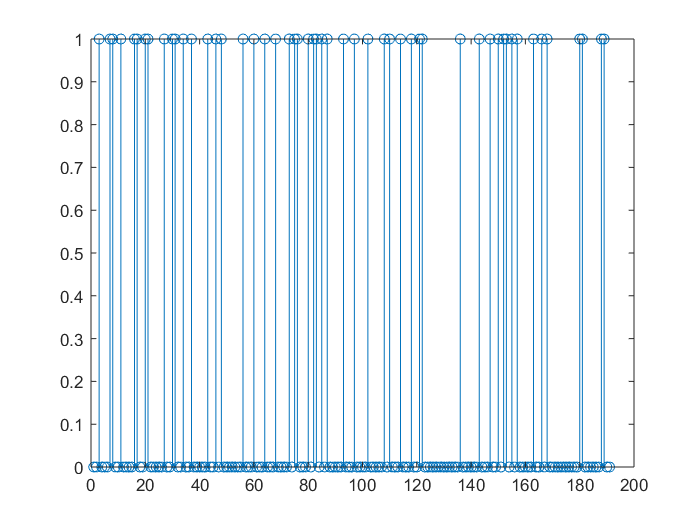

for i=1:2
    LIVEE=r1(:,i).*LIVEE;
end
%通过以下函数计算出测试集个体的预测生死，结果存至liveeE
for i=1:191
    q=rand(1);
    if(LIVEE(i,1)>rand)
        liveeE(1,i)=1;
    end
end
%绘制出预测生死，并判断正确率，正确率存至rate
right=0;
stem(liveeE);

for i=1:191
    if(liveeE(i)==data(TT(i,1),2))
        right=1+right;
    end
end
rate=right/191            %rate为测试中预测的正确率

rate = 0.6702


r=zeros(418,8);
r(:,1)=abc(T,quan3,2,418);
r(:,2)=abc(T,quan4,3,418);
r(:,3)=abc(T,quan5,4,418);
r(:,4)=abc(T,quan6,5,418);
r(:,5)=abc(T,quan7,6,418);
r(:,6)=abc(T,quan8,7,418);
r(:,7)=abc(T,quan9,8,418);
r(:,8)=abc(T,quan10,9,418);
%预测测试集（418）的存活率
LIVE=ones(418,1);
livee=zeros(1,418)

livee =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


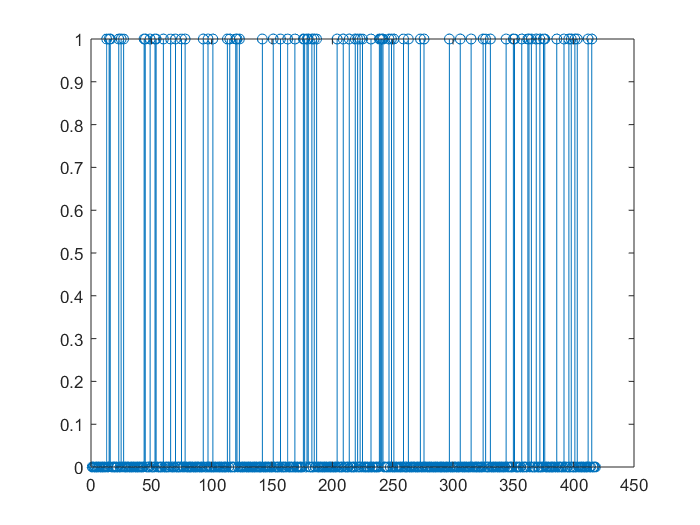

for i=1:2   %取兄弟姐妹数与性别进行评估
    LIVE=r(:,i).*LIVE;
end
for i=1:418
    if(LIVE(i,1)>=0.5)
        livee(1,i)=1;
    end
end
stem(livee); %预测的418个人的存活率

livee=livee';

function aa=abc(T,quan3,W,M)
    a3=length(quan3(:,1));
for i=1:M
    for j=1:a3
        m=T(i,W);
        n=quan3(j,1);
    if(m==n)
        r(i,1)=quan3(j,2);
        break;
    end
    if(j==a3)
        r(i,1)=1;
    end
    end
end
aa=r;
end

            
function out=en(data,x3,lie,sur1)
    jj=unique(data(:,lie));
    max3=length(jj(:,1));
        p=zeros(max3,2);
        p(:,1)=jj;
        for n=1:max3
            p(n,2)=(x3(n,3)*sur1)/x3(n,2);
        end
        out=p;
end
function output=gailv(data,lie,sur)
    jj=unique(data(:,lie));
    max3=length(jj(:,1));
    num3=zeros(max3,3);
    num3(:,1)=jj;
    for i=1:max3
        for j=1:700
            if(data(j,lie)==num3(i,1))
                num3(i,2)=num3(i,2)+1;%第二列为特征个数/总数（p（x））
                if(data(j,2)==1)
                    num3(i,3)=num3(i,3)+1;%第四列为有此特征又存活p（xw）
                end
            end
        end
    end
    num3(:,3)=num3(:,3)./sur;%有i个兄弟的情况下活下来的概率p(x|w)
    num3(:,2)=num3(:,2)./891;%有i个兄弟的概率,p(x)
    output=num3;
end



